# m0516 Script for Plotting Roll Estimation based on Ride Height Comparison

## Load Matfiles if replotting results

% load('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\CorneringBank_Test.mat')

## Find the means and ranges of the actual quantities

xl = [30 Time(end)];

index_xl_start = find(Time==xl(1))

index_xl_start = 30001


mean_CM_BodyRoll_rad = mean(CM_BodyRoll_rad(index_xl_start:end));

mean_CM_BodyRollVel_radps = mean(CM_BodyRollVel_radps);

mean_CM_RoadBank_rad = mean(CM_RoadBank_rad);

range_CM_BodyRoll_rad = max(CM_BodyRoll_rad(index_xl_start:end)) - min(CM_BodyRoll_rad(index_xl_start:end))

range_CM_BodyRoll_rad = 0.0726


range_CM_BodyRollVel_radps = max(CM_BodyRollVel_radps) - min(CM_BodyRollVel_radps)

range_CM_BodyRollVel_radps = 0.0094


range_CM_RoadBank_rad = max(CM_RoadBank_rad) - min(CM_RoadBank_rad)

range_CM_RoadBank_rad = 0

## Find Root Mean Square Errors for Roll Angle Estimates

error_Est_BodyRoll_Equation_rad = CM_BodyRoll_rad - Est_BodyRoll_Equation_rad;

RMSE_Est_BodyRoll_Equation_rad = rms(error_Est_BodyRoll_Equation_rad(index_xl_start:end))

RMSE_Est_BodyRoll_Equation_rad = 8.7296e-04


NRMSE_Est_BodyRoll_Equation_rad = RMSE_Est_BodyRoll_Equation_rad/range_CM_BodyRoll_rad

NRMSE_Est_BodyRoll_Equation_rad = 0.0120


error_Est_BodyRoll_Static_rad = CM_BodyRoll_rad - Est_BodyRoll_Static_rad;

RMSE_Est_BodyRoll_Static_rad = rms(error_Est_BodyRoll_Static_rad(index_xl_start:end))

RMSE_Est_BodyRoll_Static_rad = 0.0013


NRMSE_Est_BodyRoll_Static_rad = RMSE_Est_BodyRoll_Static_rad/range_CM_BodyRoll_rad

NRMSE_Est_BodyRoll_Static_rad = 0.0178

## Find Root Mean Square Errors for Roll Velocity Estimates

% error_Est_BodyRollVel_CF_radps = CM_BodyRollVel_radps - Est_BodyRollVel_CF_radps;
% 
% RMSE_Est_BodyRollVel_CF_radps = rms(error_Est_BodyRollVel_CF_radps);
% 
% NRMSE_Est_BodyRollVel_CF_radps = RMSE_Est_BodyRollVel_CF_radps/range_CM_BodyRollVel_radps

% error_Est_BodyRollVel_Fr2q0_radps = CM_BodyRollVel_radps - Est_BodyRollVel_Fr2q0_radps;
% 
% RMSE_Est_BodyRollVel_Fr2q0_radps = rms(error_Est_BodyRollVel_Fr2q0_radps)
% 
% NRMSE_Est_BodyRollVel_Fr2q0_radps = RMSE_Est_BodyRollVel_Fr2q0_radps/range_CM_BodyRollVel_radps


## Find Root Mean Square Errors for Bank Angle Estimates

% error_Est_RoadBank_rad = CM_RoadBank_rad - Est_RoadBank_rad;
% 
% RMSE_Est_RoadBank_rad = rms(error_Est_RoadBank_rad);
% RMSE_Est_RoadBank_deg = RMSE_Est_RoadBank_rad*180/pi
% 
% NRMSE_Est_RoadBank_rad = RMSE_Est_RoadBank_rad/range_CM_RoadBank_rad


## Convert radians to degrees

CM_BodyRollVel_degps = CM_BodyRollVel_radps*180/pi;
Est_BodyRollVel_CF_degps = Est_BodyRollVel_CF_radps*180/pi;

CM_Roll_deg = CM_Roll_rad*180/pi;
CM_RollVel_degps = CM_RollVel_radps*180/pi;

CM_BodyRoll_deg = CM_BodyRoll_rad*180/pi;
Est_BodyRoll_Static_deg = Est_BodyRoll_Static_rad*180/pi;
Est_BodyRoll_Equation_deg = Est_BodyRoll_Equation_rad*180/pi;

CM_RoadBank_deg = CM_RoadBank_rad*180/pi;
Est_RoadBank_deg = Est_RoadBank_rad*180/pi;


## Setting Plotting Variables

legend_fontsize = 16;
title_fontsize = 16;

## Plot Ride Height Derived Roll Angle Estimates and Error

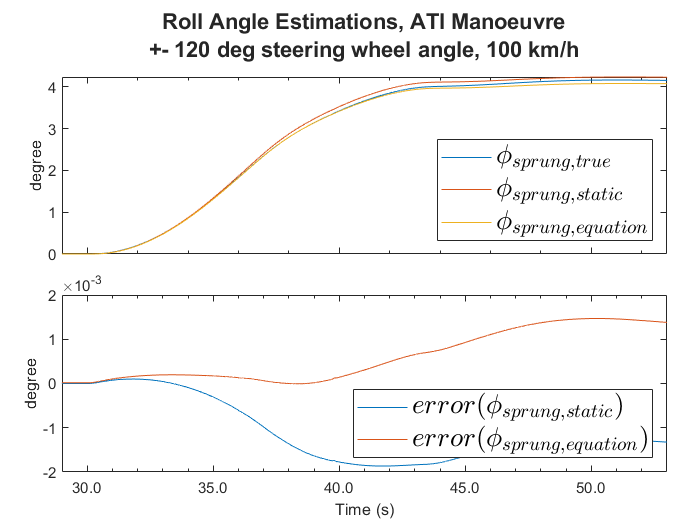

%define x and y axis limits
xl1 = xl-1;
% xl1 = [9 18];
figure(1)
clf
t1 = tiledlayout(2,1);


ax1a = nexttile;

plot(Time,CM_BodyRoll_deg,Time,Est_BodyRoll_Static_deg,Time,Est_BodyRoll_Equation_deg)  
legend ("$\phi_{sprung,true}$",'$\phi_{sprung,static}$','$\phi_{sprung,equation}$','Interpreter','latex','FontSize',legend_fontsize,'location','southeast')
ylabel('degree')

ax1b = nexttile;
plot(Time,error_Est_BodyRoll_Static_rad,Time,error_Est_BodyRoll_Equation_rad)
legend ('$error(\phi_{sprung,static})$','$error(\phi_{sprung,equation})$','Interpreter','latex','FontSize',legend_fontsize,'location','southeast')
ylabel('degree')
% 
% ax1c = nexttile;
% plot(Time,Est_BodyRoll_CF_deg,...
%     Time,CM_BodyRoll_deg);
% legend ("$\phi_{sprung,est}$","$\phi_{sprung,true}$",'Interpreter','latex', ...
%     'FontSize',11,'location','northwest')
% %    "Ride Height Estimated Sprung Body Roll Angle (deg)", ...  
% ylabel('deg')

%Combine the subplots
linkaxes([ax1a,ax1b],'x')

title(t1, {'Roll Angle Estimations, ATI Manoeuvre', '+- 120 deg steering wheel angle, 100 km/h'})
% title(t1, {'Roll Angle Estimations, Step Steer, 400 deg steering wheel angle, 100 km/h'})
% title(t1, {'Open Loop Roll Angle Estimations, Ramp Steer, 200 deg max steering wheel angle, 15 deg/s, 60 km/h'})
% title(t1, {'Open Loop Roll Angle Estimations, Sine with Dwell'})
t1.Title.FontWeight = 'bold';
% t1.Title.FontSize = 11;
xlabel('Time (s)');
% xticks(xl(1):1:xl(2))
set([ax1a ax1b],'XMinorTick','on')
xtickformat('%.1f')
xticklabels([ax1a],{})

t1.Padding = 'compact';
t1.TileSpacing = 'compact';

    xlim(xl1) 

## Save Result (filename for each testrun)

%% Cornering at Banked Angle

% rawfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\CorneringBank_Test.mat');
% save(rawfilename,'Time','CM_BodyRoll_rad', 'CM_BodyRollVel_radps', 'CM_RoadBank_rad', ...
%     'Est_BodyRollVel_CF_radps','Est_BodyRoll_CF_rad','Est_BodyRoll_Fr2q0_rad','Est_BodyRoll_Fr2q0_rad')
% 
% NRMEfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\CorneringBank_Test\NRMSE.mat');
% save(NRMEfilename,'Time', 'NRMSE_Est_BodyRollVel_CF_radps','NRMSE_Est_RoadBank_rad', ...
%     'NRMSE_Est_BodyRoll_CF_rad','NRMSE_Est_BodyRoll_Fr2q0_rad')

% rawfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\Sine with Dwell\Sine_with_Dwell.mat');
% save(rawfilename,'Time','CM_BodyRoll_rad', 'CM_BodyRollVel_radps', 'CM_RoadBank_rad', ...
%     'Est_BodyRollVel_CF_radps','Est_BodyRoll_CF_rad','Est_BodyRoll_Fr2q0_rad','Est_BodyRoll_Fr2q0_rad')
% 
% NRMEfilename=('C:\Users\jason\Cranfield University\2021-AM-GDP-Team1-UGT-SATM - General\Report and Poster\05_SE\Sine with Dwell\NRMSE.mat');
% save(NRMEfilename,'Time', 'NRMSE_Est_BodyRollVel_CF_radps','NRMSE_Est_RoadBank_rad', ...
%     'NRMSE_Est_BodyRoll_CF_rad','NRMSE_Est_BodyRoll_Fr2q0_rad')
